# Getting started with bombcell

## Set paths

Toy dataset location you can play around with. This only has a few units to make it lightweight and easy to load.

toy_dataset_location = './demos/toy_data/';

These paths below are the paths you will need to input to load data and save the computed quality metrics / ephys properties. Here we are leaving ephysRawFile as "NaN" to not load raw data (it is too cumbersome to store these large files on github). All metrics relating to raw data (amplitude, ) will not be computed. 

ephysKilosortPath = toy_dataset_location;
ephysRawFile = "NaN"; % path to your raw .bin or .dat data
ephysMetaDir = dir([toy_dataset_location '*ap*.*meta']); % path to your .meta or .oebin meta file
savePath = [toy_dataset_location 'qMetrics']; % where you want to save the quality metrics 

Two paramaters to pay attention to: the kilosort version (change to kilosortVersion = 4 if you are using kilosort4) and the gain_to_uV scaling factor (xx).

kilosortVersion = 2;% if using kilosort4, you need to change this value. Otherwise it does not matter. 
gain_to_uV = NaN; % use this if you are not using spikeGLX or openEphys to record your data

## Load data

This function loads are your ephys data. Use this function rather than any custom one as it handles zero-indexed values in a particular way. 

[spikeTimes_samples, spikeTemplates, templateWaveforms, templateAmplitudes, pcFeatures, ...
    pcFeatureIdx, channelPositions] = bc.load.loadEphysData(ephysKilosortPath);

## Run quality metrics

Set your paramaters. These define both how you will run quality metrics and how thresholds will be applied to quality metrics to classiofy units into good/MUA/noise/non-axonal. This function loads default, permissive values. It's highly recommended for you to iteratively tweak these values to find values that suit your particular use case! 

param = bc.qm.qualityParamValues(ephysMetaDir, ephysRawFile, ephysKilosortPath, gain_to_uV, kilosortVersion);

Run all your quality metrics! This function runs all quality metrics, saves the metrics in your savePath folder and outputs some global summary plots that can give you a good idea of how things went. 


 Removed 143 spike duplicates out of 94565 total spikes. 

 Extracting quality metrics from NaN ... 

   Finished 15 / 15 units.
 Finished extracting quality metrics from NaN
 Saved quality metrics from NaN to ./demos/toy_data/qMetrics 


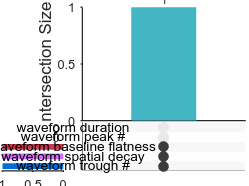

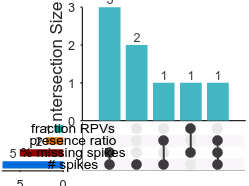

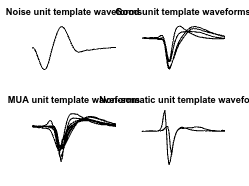

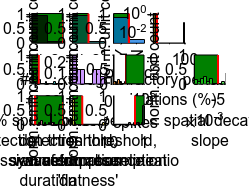

[qMetric, unitType] = bc.qm.runAllQualityMetrics(param, spikeTimes_samples, spikeTemplates, ...
        templateWaveforms, templateAmplitudes, pcFeatures, pcFeatureIdx, channelPositions, savePath);

## Inspect

After running quality metrics, espacially the first few times, it's a good idea to inspect your data and the quality metrics using the built-in GUI. Use your keyboard to navigate the GUI: 

- left/right arrow: toggle between units 

- g : go to next good unit 

- m : go to next multi-unit 

- n : go to next noise unit

- up/down arrow: toggle between time chunks in the raw data

-  u: brings up a input dialog to enter the unit you want to go to


loadRawTraces = 0; % default: don't load in raw data (this makes the GUI significantly faster)
bc.load.loadMetricsForGUI;


 Removed 143 spike duplicates out of 94565 total spikes. 


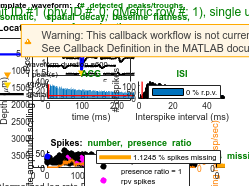


unitQualityGuiHandle = bc.viz.unitQualityGUI(memMapData, ephysData, qMetric, forGUI, rawWaveforms, ...
    param, probeLocation, unitType, loadRawTraces);

## Run ephys properties

rerunEP = 0;
region = ''; % options include 'Striatum' and 'Cortex'
[ephysProperties, unitClassif] = bc.ep.runAllEphysProperties(ephysKilosortPath, savePath, rerunEP, region);


 Removed 143 spike duplicates out of 94565 total spikes. 

 Extracting ephys properties ... 
   Finished 15 / 15 units.
 Finished extracting ephys properties
 Saved ephys properties to ./demos/toy_data/qMetrics 
